## **Section 1: Setup and Parameters**

This section defines the environment, the number of agents, and the coefficients for the three governing rules (Separation, Alignment, Cohesion)

% --- Simulation Constants ---
numBoids = 50;              % Number of agents
steps = 500;                % Number of time steps to run
envSize = 100;              % 100x100 units
visualRange = 15;           % Radius to detect neighbors
protectedRange = 4;         % Separation distance (personal space)

% --- Physics Limits ---
maxSpeed = 2;               % Speed limit for boids
predatorMaxSpeed = 2.5;     % Predator is slightly faster

% --- Rule Weights (Tunable Parameters) ---
% Adjust these to see emergent behavior changes!
separationFactor = 0.5;     % Strength of avoidance
alignmentFactor  = 0.15;    % Strength of matching heading
cohesionFactor   = 0.05;    % Strength of staying together
predatorAvoidFactor = 5.0;  % Strength of running from predator

% --- Toggle Extensions ---
enablePredator = true;      % Set to false to disable the predator

## Section 2: Initialization

Here we create the data structures for positions and velocities. We utilize random values to ensure every simulation run is unique.

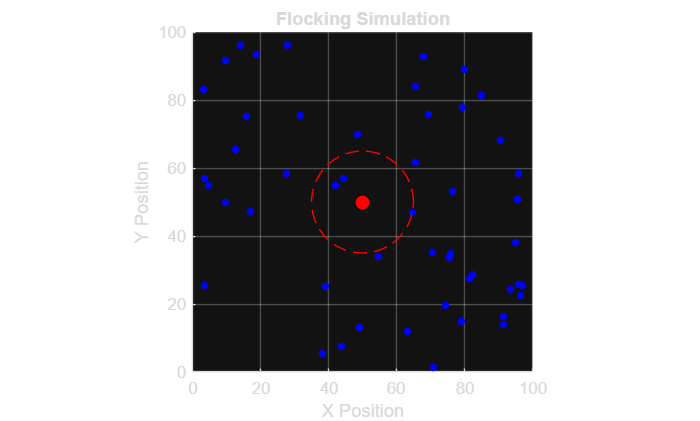

% Initialize Boids
% Positions: Random [x, y] between 0 and envSize
positions = rand(numBoids, 2) * envSize;

% Velocities: Random vectors between -1 and 1, then scaled
velocities = (rand(numBoids, 2) - 0.5) * 2; 

% Initialize Predator (Start in the middle)
predPos = [envSize/2, envSize/2];
predVel = [1, 2]; % Initial movement

% Setup the Figure for Animation
figure('Name', 'Boids Flocking Simulation', 'Color', 'w');
axis equal;
axis([0 envSize 0 envSize]);
hold on;
grid on;

% Create plot handles for efficient updating
hBoids = scatter(positions(:,1), positions(:,2), 20, 'b', 'filled');

if enablePredator
    hPred = scatter(predPos(1), predPos(2), 80, 'r', 'filled', 'MarkerEdgeColor', 'k');
    
    % --- FIX: Create a permanent circle object using 'plot' instead of 'viscircles' ---
    theta = linspace(0, 2*pi, 50); % Create angles for a circle
    % Initialize circle at (0,0) - we will move it later
    circX = visualRange * cos(theta); 
    circY = visualRange * sin(theta);
    hVisCircle = plot(circX + predPos(1), circY + predPos(2), 'r--', 'LineWidth', 0.5);
end

title('Flocking Simulation');
xlabel('X Position');
ylabel('Y Position');

## Section 3: The Simulation Loop

This is the core engine. For every time step, we calculate the forces for every single boid based on its neighbors.

**Key Logic:**

- **Separation:** If a neighbor is *too close* protectedRange, steer away.

- **Alignment:** Calculate the average velocity of neighbors and steer to match it.

- **Cohesion:** Calculate the center of mass of neighbors and steer toward it.

- **Predator Avoidance:** If the predator is close, create a massive repulsion force.

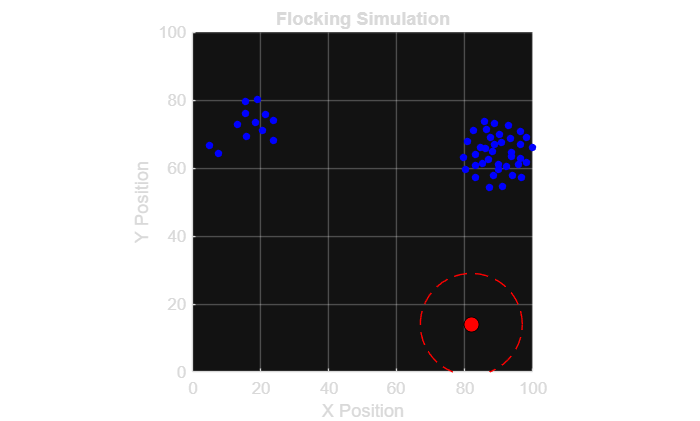

%% Simulation Loop
for t = 1:steps
    
    % Prepare arrays to store updates (so we don't update while reading)
    posUpdate = zeros(numBoids, 2);
    velUpdate = zeros(numBoids, 2);
    
    % Loop through each boid
    for i = 1:numBoids
        
        % Current boid state
        p = positions(i, :);
        v = velocities(i, :);
        
        % Initialize Force Vectors
        sepForce = [0, 0];
        alignForce = [0, 0];
        cohForce = [0, 0];
        predForce = [0, 0];
        
        neighborsCount = 0;
        avgVel = [0, 0];
        avgPos = [0, 0];
        
        % --- Check Neighbors ---
        for j = 1:numBoids
            if i == j, continue; end % Don't check self
            
            % Calculate distance (accounting for wrap-around boundaries is complex, 
            % so we use simple Euclidean here for basic simulation)
            d = norm(positions(j,:) - p);
            
            if d < visualRange
                neighborsCount = neighborsCount + 1;
                
                % 1. Separation: If too close, move away
                if d < protectedRange
                    diff = p - positions(j,:); % Vector pointing away
                    sepForce = sepForce + (diff / d); % Weight by distance
                end
                
                % Accumulate data for Alignment and Cohesion
                avgVel = avgVel + velocities(j, :);
                avgPos = avgPos + positions(j, :);
            end
        end
        
        % --- Process Group Rules ---
        if neighborsCount > 0
            % 2. Alignment: Steer towards average heading
            avgVel = avgVel / neighborsCount;
            alignForce = (avgVel - v); 
            
            % 3. Cohesion: Steer towards average position
            avgPos = avgPos / neighborsCount;
            cohForce = (avgPos - p);
        end
        
        % --- Extension: Predator Avoidance ---
        if enablePredator
            distToPred = norm(predPos - p);
            if distToPred < visualRange * 1.5
                % Strong vector away from predator
                predForce = (p - predPos) / distToPred; 
            end
        end
        
        % --- Update Velocity ---
        % Combine forces with weights
        totalForce = (sepForce * separationFactor) + ...
                     (alignForce * alignmentFactor) + ...
                     (cohForce * cohesionFactor) + ...
                     (predForce * predatorAvoidFactor);
                 
        v_new = v + totalForce;
        
        % Enforce Max Speed
        speed = norm(v_new);
        if speed > maxSpeed
            v_new = (v_new / speed) * maxSpeed;
        end
        
        velUpdate(i, :) = v_new;
        
        % Update Position
        pos_new = p + v_new;
        
        % --- Boundary Conditions (Wrap-Around / Toroidal) ---
        % If boid goes off right edge, appears on left, etc.
        pos_new(1) = mod(pos_new(1), envSize);
        pos_new(2) = mod(pos_new(2), envSize);
        
        posUpdate(i, :) = pos_new;
    end
    
    % Update the global arrays
    positions = posUpdate;
    velocities = velUpdate;

    %%-----New Updated code to avoid the live script crash.-----%%

    % ... [Inside the Simulation Loop] ...

    % --- Update Predator Logic ---
    if enablePredator
        % [Existing predator movement code...]
        
        predPos = predPos + predVel;
        predPos(1) = mod(predPos(1), envSize);
        predPos(2) = mod(predPos(2), envSize);
        
        % Update Predator Dot
        set(hPred, 'XData', predPos(1), 'YData', predPos(2));
        
        % --- FIX: Update the circle position without deleting it ---
        % Simply shift the X and Y data to the new predator position
        set(hVisCircle, 'XData', circX + predPos(1), 'YData', circY + predPos(2));
    end
    
    % --- Visualization Update ---
    set(hBoids, 'XData', positions(:,1), 'YData', positions(:,2));
    pause(0.1);
end